# Prediction of metabolic engineering targets for increased production of 2-phenyethanol in *Saccharomyces cerevisiae* using ecYeastGEM and ecFactory

### 1.- Clone the ecModels repository and load ecYeastGEM_batc

clear
git clone --quiet --depth=1 https://github.com/SysBioChalmers/ecModels.git

fatal: destination path 'ecModels' already exists and is not an empty directory.



clc
load('ecModels/ecYeastGEM/model/ecYeastGEM_batch.mat')
ecModel = ecModel_batch;

### 2.- Clone GECKO inside ecFactory/code

cd ../code
git clone --quiet --branch v2.0.3 --depth=1 https://github.com/SysBioChalmers/GECKO.git

fatal: destination path 'GECKO' already exists and is not an empty directory.



### 3.- Set case-specific parameters

Create a structure with the following model-specific parameters

- `modelParam.CSrxn = preferred carbon source uptake reaction ID`

- `modelParam.CS_MW = Molecular weight of the preferred carbon source`

- `modelParam.growthRxn = Growth reaction name`

- `modelParam.rxnTarget = ID for the production target reaction`

%Find carbon source uptake reaction 
CSname = 'D-glucose exchange (reversible)';
modelParam.CSrxn  = ecModel.rxns{strcmpi(ecModel.rxnNames,CSname)};
%Indicate carbon source mol. weight in grams/mmol
modelParam.CS_MW  = 0.18015;
%Indicate the name of the growth or biomass pseudoreaction
modelParam.growthRxn = ecModel.rxns{strcmpi(ecModel.rxnNames,'biomass pseudoreaction')};
%identify the production target reaction
product_name         = '2-phenylethanol';
target_pos           = find(strcmpi(ecModel.rxnNames,[product_name ' exchange']));
modelParam.rxnTarget = ecModel.rxns(target_pos);
disp(['*The production reaction for ' product_name ' has been found under the ID: ' modelParam.rxnTarget{1}])

*The production reaction for 2-phenylethanol has been found under the ID: r_1589


Provide a directory path for the results files

%results folder name
results_folder = '../tutorials/results/2_phenylethanol_targets';
mkdir(results_folder)
%get current directory
current = pwd;

### 4.-constrain ecModel

%Set media conditions for batch growth
const_ecModel = changeMedia_batch(ecModel,CSname,'Min'); %model-specific script

CS_index      = find(strcmpi(const_ecModel.rxns,modelParam.CSrxn));
growthPos     = find(strcmpi(const_ecModel.rxns,modelParam.growthRxn));
%Enable cellular growth
const_ecModel = setParam(const_ecModel,'lb',growthPos,0);
const_ecModel = setParam(const_ecModel,'ub',growthPos,1000);
%block artificial growth
revIndex = find(strcmpi(const_ecModel.rxnNames,'growth (reversible)'));
const_ecModel.lb(revIndex) = 0;
const_ecModel.ub(revIndex) = 0;
%Set a fixed unit glucose uptake rate
const_ecModel = setParam(const_ecModel,'ub',CS_index,1);

### 5.- Get a feasible biomass yield range to be scanned by the ecFactory method

%Get biomass yield for a unit glucose uptake rate
const_ecModel = setParam(const_ecModel,'obj',growthPos,1);
solution      = solveLP(const_ecModel,1);
WT_yield      = solution.x(growthPos)/(solution.x(CS_index)*modelParam.CS_MW);
disp(['* The maximum biomass yield is ' num2str(WT_yield) '[g biomass/g carbon source]']);

* The maximum biomass yield is 0.48368[g biomass/g carbon source]


%Obtain a suboptimal yield value to run ecFactory
expYield = 0.49*WT_yield;
disp('* The ecFactory method will scan flux distributions spanning from')

* The ecFactory method will scan flux distributions spanning from


disp(['a suboptimal biomass yield of: ' num2str(0.5*expYield) ' to: ' num2str(2*expYield) ' [g biomass/g carbon source]']);

a suboptimal biomass yield of: 0.1185 to: 0.474 [g biomass/g carbon source]


### 7.- Run ecFactory method

* Your ecModel can carry flux through the reaction: 2-phenylethanol exchange


1.-  **** Running ecFSEOF method (from GECKO utilities) ****
  
ecFSEOF returned 44 targets
  
 Extracting enzymatic information for target genes
  
Removing targets 0.5 < K_score < 1.05
 * 43 gene targets remain
  
2.-  **** Find flux leak targets to block ****
 Target molecule: 2-phenylethanol
 * 45 gene targets remain
  
3.-  **** Removing essential genes from KD and KO targets list ****
 * 45 gene targets remain
  
4.-  **** Construct Genes-metabolites network for classification of targets ****
  
  Constructing genes-metabolites graph
  
  Obtain redundant vectors in genes-metabolites graph (redundant targets)
  
5.-  **** Running EUVA for optimal production conditions (minimal biomass) ****
 
  - Fixed unit glucose uptake rate
  - Fixed suboptimal biomass production, according to provided experimental yield
    V_bio = 0.042696 h-1
  - Production rate constrained to its maximum attainable value
    V_prod_max = 0.27864 mmol/gDwh
 
* Discard targets according to EUVA results for o

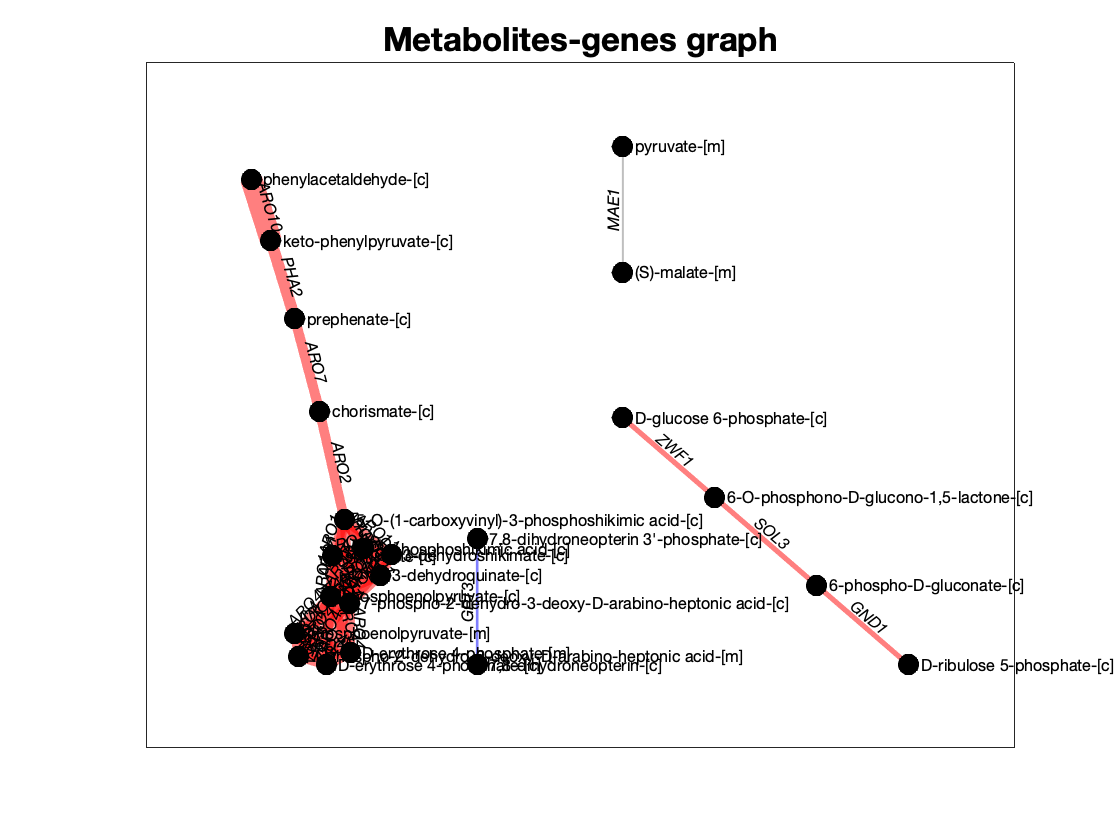

 * The predicted optimal strain contains 13 gene modifications
 
9.-  **** Find transporter reactions with no enzyme association predicted as targets by ecFSEOF ****
 
 * 7 transport reaction targets were found
 


try
    [optStrain,candidates,step] = run_ecFactory(const_ecModel,modelParam,expYield,results_folder,true);
catch
    disp('The model is not suitable for the ecFactory method')
end

cd (current)

### 8.- Get a flux distribution of the optimal strain model

solution = solveLP(optStrain,1);
printFluxes(optStrain,solution.x,true)

EXCHANGE FLUXES:
r_1589	(2-phenylethanol exchange):	0.27864
r_1672	(carbon dioxide exchange):	1.4512
r_1793	(formate exchange):	0.93993
r_1814	(glycolaldehyde exchange):	2.7582e-06
r_2100	(water exchange):	3.057
r_2111	(growth):	0.042696
r_1654_REV	(ammonium exchange (reversible)):	0.29251
r_1714_REV	(D-glucose exchange (reversible)):	1.0617
r_1832_REV	(H+ exchange (reversible)):	0.0119
r_1861_REV	(iron(2+) exchange (reversible)):	1.3407e-06
r_1992_REV	(oxygen exchange (reversible)):	1.2812
r_2005_REV	(phosphate exchange (reversible)):	0.011676
r_2020_REV	(potassium exchange (reversible)):	0.00015499
r_2049_REV	(sodium exchange (reversible)):	0.0001695
r_2060_REV	(sulphate exchange (reversible)):	0.0039085
r_4593_REV	(chloride exchange (reversible)):	5.5078e-05
r_4594_REV	(Cu2(+) exchange (reversible)):	2.8137e-05
r_4595_REV	(Mn(2+) exchange (reversible)):	0.00011656
r_4596_REV	(Zn(2+) exchange (reversible)):	3.1937e-05
r_4597_REV	(Mg(2+) exchange (reversible)):	5.3051e-05
r_4600_REV	(

### 9.- Remove ecModels repository files

cd ../tutorials
rmdir ecModels